ex montecarlo prezzo future

% Parameters
Rf = 0.06;
sigma = 0.12;
startPrice = 100;
F=100*exp(0.06*(200/252))

F = 104.8771

K = 100;
T = 200;
Delta = T/5; % Step length
year = 252;
t = Delta/year;
u = exp(sigma*sqrt(t));
d = exp(-sigma*sqrt(t));

% Black-Scholes price
[call,put]=blsprice(startPrice,K,Rf,200/252,sigma)

call = 6.8948

put = 2.2445

[call,put] = blkprice(F, K, Rf, T/year, sigma)

call = 6.8948

put = 2.2445

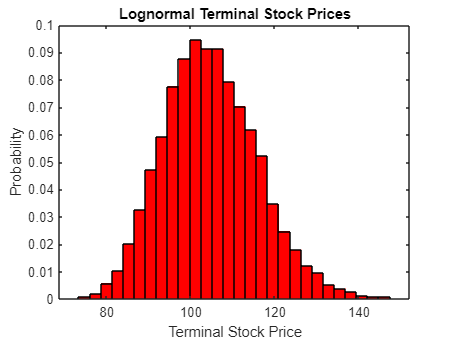

% le derivate le possiamo calcolare attraverso l'uso della put call parity





% Stock price simulation
ExpReturn = [0];
Sigmas = [sigma^2];
correlation = [sigma^2];
ExpCovariance = sigma^2;
NumObs = 200;
NumSim = 10000;
RetIntervals = 1/year;
rng('default');  
RetExpected = portsim(ExpReturn, ExpCovariance, NumObs, RetIntervals, NumSim, 'Expected');
ExpSimulation = squeeze(RetExpected);

% Find stock prices
StockPrices = ret2tick(ExpSimulation, repmat(F, 1, NumSim));

% Histogram
[count, BinCenter] = hist(StockPrices(end,:), 30);
figure(1)
bar(BinCenter, count/sum(count), 1, 'r')
xlabel('Terminal Stock Price')
ylabel('Probability')
title('Lognormal Terminal Stock Prices')

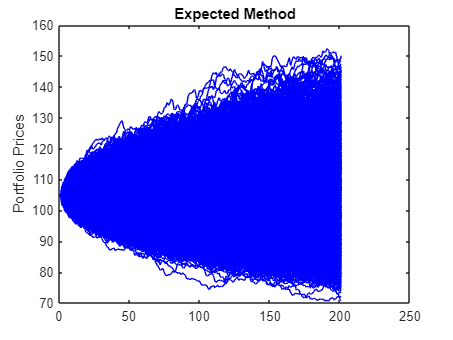


% Plot
plot(StockPrices, '-b')
ylabel('Portfolio Prices')
title('Expected Method')


% Call pricing
term = StockPrices(201,:)';
payoff = (term - K);
payoff(payoff < 0) = 0;
callmontecarlo = mean(payoff)*exp(-0.06*(200/252))

callmontecarlo = 6.8943


% Put pricing
payoff1 = (K - term);
payoff1(payoff1 < 0) = 0;
putmontecarlo = mean(payoff1)*exp(-0.06*(200/252))

putmontecarlo = 2.2363